# Fahrkennfelder

### Motorkennlinien

gegeben: Stützstellen für die Momentenkennlinie

n_VM_rpm = [1000 1500 2000 2500 3000 4000 5000 5500 6000];  % Drehzahlstützstellen
M_VM_Nm = [100 150 200 225 250 250 250 215 180];            % Drehmomentstützstellen

Umrechnung in die Leistungskennlinie mit 


$$P_{VM}=M_{VM}\cdot\frac{\pi}{30}\cdot n_{VM}
$$


P_VM_kW = M_VM_Nm .* (pi/30*n_VM_rpm) ./1000;

Grafische Darstellung der Motorkennlinien

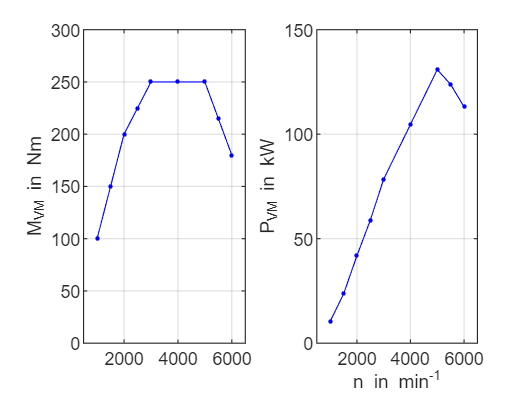

figure
subplot(1,2,1);
    plot(n_VM_rpm,M_VM_Nm,'b.-')
    hold on
    ylabel('M_{VM} in Nm')
    grid on
    xlim([500 6500])
    ylim([0 300])
subplot(1,2,2);
   plot(n_VM_rpm,P_VM_kW,'b.-')
    hold on
    xlabel('n in min^{-1}')
    ylabel('P_{VM} in kW')
    grid on
    xlim([500 6500])
    ylim([0 150])

### Antriebsdaten

fiktive Getriebeübersetzungen (4 Gänge)

i_G = [6 3 1.5 0.75];           % fiktive Getriebeübersetzungen (4 Gänge)
i_A     =2.5;
eta_A   = 0.9;  % Antriebswirkungsgrad
r_A     = 0.3;  % Reifenradius

### **Kräfte und Leistungen am Rad**

Antriebskräfte                    $F_A = \eta_A \cdot M_{VM}\cdot \frac{i_G\cdot i_A}{r_A}$

F_A1 = eta_A*M_VM_Nm*i_G(1)*i_A/r_A;
F_A2 = eta_A*M_VM_Nm*i_G(2)*i_A/r_A;
F_A3 = eta_A*M_VM_Nm*i_G(3)*i_A/r_A;
F_A4 = eta_A*M_VM_Nm*i_G(4)*i_A/r_A;

Antriebsleistung                $P_A = \eta_A \cdot P_{VM}$

P_A = eta_A*P_VM_kW;

Fahrwiderstand am Rad    $F_W = m\cdot g \cdot \sin \alpha + f_R\cdot m \cdot g \cdot \cos \alpha + c_w\cdot A \cdot \frac{\rho}{2} \cdot v^2$

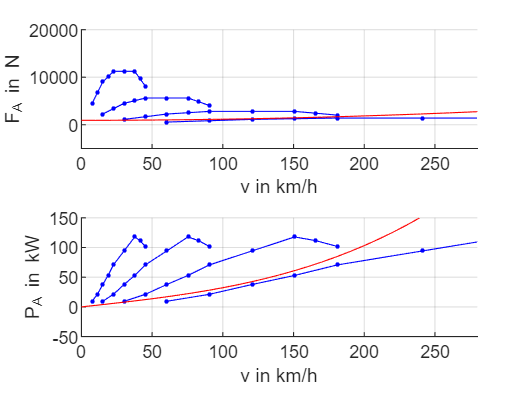

fR = 0.01;
cw = 0.25;
Willanslinien = 2;
m = 1500;
g = 9.81;
rho = 1.2;

v_W_kph = [0:10:280];  % Geschwindigkeitsstützstellen
v_W_mps = v_W_kph/3.6;

q = 7;
alpha = atand(q/100);

F_W = m*g*sind(alpha) + fR*m*g*cos(alpha) + cw*Willanslinien*rho/2*v_W_mps.^2;
P_W_kW = F_W.*v_W_mps/1000;

% Umrechnung der Drehzahlstützstellen in Geschwindigkeitsstützstellen
v_G1_kph = pi/30*n_VM_rpm*r_A/(i_G(1)*i_A)*3.6;
v_G2_kph = pi/30*n_VM_rpm*r_A/(i_G(2)*i_A)*3.6;
v_G3_kph = pi/30*n_VM_rpm*r_A/(i_G(3)*i_A)*3.6;
v_G4_kph = pi/30*n_VM_rpm*r_A/(i_G(4)*i_A)*3.6;

figure
subplot(2,1,1)
    grid on
    hold on
    plot(v_G1_kph,F_A1,'b.-')
    plot(v_G2_kph,F_A2,'b.-')
    plot(v_G3_kph,F_A3,'b.-')
    plot(v_G4_kph,F_A4,'b.-')
    plot(v_W_kph,F_W,'r')
    xlabel('v in km/h')
    ylabel('F_{A} in N')
    xlim([0 280])
    ylim([-5000 20000])
subplot(2,1,2)
    grid on
    hold on
    plot(v_G1_kph,P_A,'b.-')
    plot(v_G2_kph,P_A,'b.-')
    plot(v_G3_kph,P_A,'b.-')
    plot(v_G4_kph,P_A,'b.-')
    plot(v_W_kph,P_W_kW,'r')
    xlabel('v in km/h')
    ylabel('P_A in kW')
    xlim([0 280])
    ylim([-50 150])

### **Fahrwiderstand im Motorkennfeld**

Momentenbedarf durch Fahrwiderstand    $M_W = \frac{1}{\eta_A} \cdot F_W \cdot \frac{r_A}{i_G \cdot i_A}$

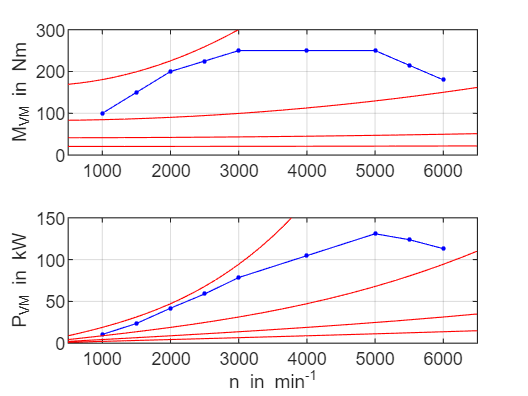

M_W1 = 1/eta_A*F_W*r_A/(i_G(1)*i_A);   
M_W2 = 1/eta_A*F_W*r_A/(i_G(2)*i_A);
M_W3 = 1/eta_A*F_W*r_A/(i_G(3)*i_A);
M_W4 = 1/eta_A*F_W*r_A/(i_G(4)*i_A);

% Geschwindigkeitsstützstellen von F_W0 in Motordrehzahl (gangabhängig)
n_W1_rpm = 30/pi*v_W_mps*i_G(1)*i_A/r_A;
n_W2_rpm = 30/pi*v_W_mps*i_G(2)*i_A/r_A;
n_W3_rpm = 30/pi*v_W_mps*i_G(3)*i_A/r_A;
n_W4_rpm = 30/pi*v_W_mps*i_G(4)*i_A/r_A;

figure
handle_M_VM=subplot(2,1,1);
    plot(n_VM_rpm,M_VM_Nm,'b.-')
    grid on
    hold on
    plot(n_W1_rpm,M_W1,'r')
    plot(n_W2_rpm,M_W2,'r')
    plot(n_W3_rpm,M_W3,'r')
    plot(n_W4_rpm,M_W4,'r')
    ylabel('M_{VM} in Nm')
    xlim([500 6500])
    ylim([0 300])
handle_P_VM=subplot(2,1,2);
    plot(n_VM_rpm,P_VM_kW,'b.-')
    grid on
    hold on
    plot(n_W1_rpm,P_W_kW/eta_A,'r')
    plot(n_W2_rpm,P_W_kW/eta_A,'r')
    plot(n_W3_rpm,P_W_kW/eta_A,'r')
    plot(n_W4_rpm,P_W_kW/eta_A,'r')
    xlabel('n in min^{-1}')
    ylabel('P_{VM} in kW')
    xlim([500 6500])
    ylim([0 150])

Willans Linie Verbrauchskennfeld (noch nicht implementiert).

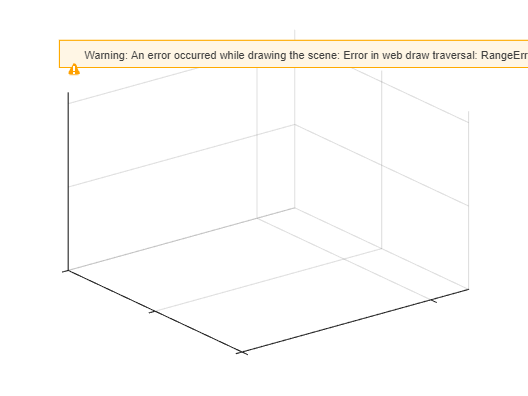

load kennfeld.mat
figure

mesh(nmo_range, mmo_range,  babs)

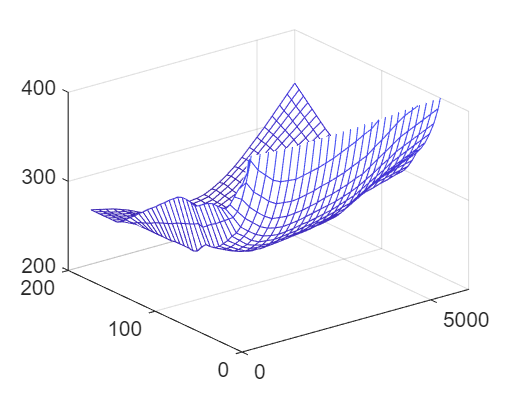

nmo_range_radps = nmo_range * (pi/30);
Leistung = nmo_range_radps  .* mmo_range' ;
b_e = babs ./ Leistung;
figure
mesh(nmo_range, mmo_range, b_e)
zlim([200 400])

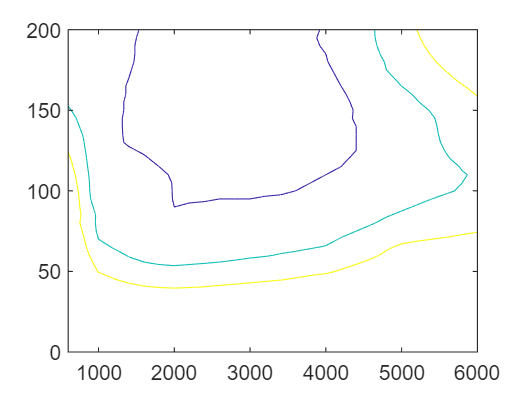


contour(nmo_range, mmo_range, b_e, [250 275 300])

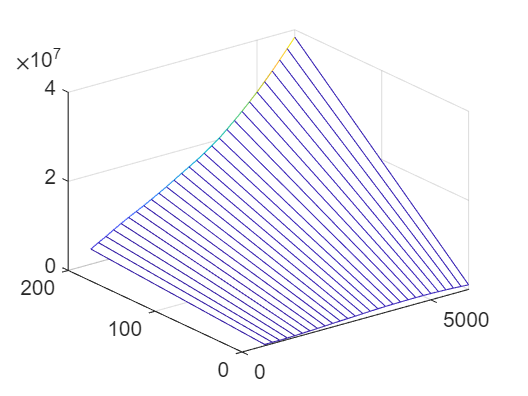



length_nmo_range = length(nmo_range);
Willanslinien = [];
mmo_willans = [0 200];
%Erzeugen Willanslinien
for i_willans = 1:length_nmo_range
babs_atnmo = babs(:,i_willans);
Ausgleichsgerade = polyfit(mmo_range, babs_atnmo, 1);
polyval_willans = polyval(Ausgleichsgerade, mmo_willans);
%Ausgleichsgerade = reshape(polyval_willans, [1,2]);
Willanslinien(:,end+1) = polyval_willans;
end
mesh(nmo_range, mmo_willans, Willanslinien)

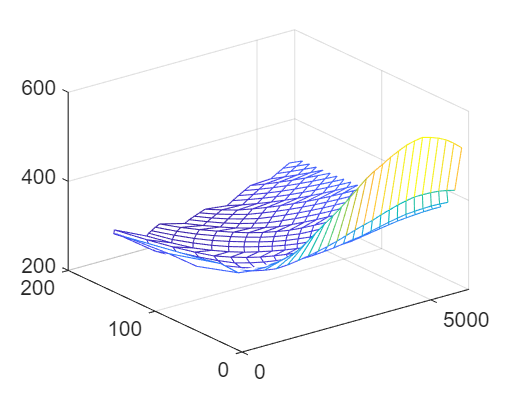



i_zaehler_row = 1;
i_zaehler_col = 1;
nmo_temp = [];
mmo_temp = [];
b_e_temp = [];
%Kurven gleicher Leistung
for i_leistung = 0:5:120   %Leistung P[kW] 20-120kW in 20er steps
   
    for i_leistung_drehzahl = 1:length_nmo_range   %jede Drehzahlgerade 
        %Stützstellen Willanslinie
        nmo_stuetzstelle_0Nm = Willanslinien(1,i_leistung_drehzahl);
        nmo_stuetzstelle_200Nm = Willanslinien(2,i_leistung_drehzahl)/200;
        nmo_muschel = nmo_range(i_leistung_drehzahl);
        %Gesuchtes Drehmoment
        m_muschel = (i_leistung*1000)/(nmo_muschel*(pi/30));
        %Geradengleichung aufstellen
        babs_muschel = nmo_stuetzstelle_0Nm + m_muschel * nmo_stuetzstelle_200Nm;        
            %liegt das gesuchte Moment in der range? wenn ja wird es in den
            %Vektor geschrieben
            if m_muschel <= 200    
               nmo_temp(i_zaehler_row, i_zaehler_col) = nmo_muschel;                    %aktuelle Drehzahl
               mmo_temp(i_zaehler_row, i_zaehler_col) = m_muschel;                      %aktuelles Moment
               b_e_temp(i_zaehler_row, i_zaehler_col) = babs_muschel/(i_leistung*1000); %Spezifischer Verbrauch
               i_zaehler_col = i_zaehler_col + 1;
            end       
    end
     i_zaehler_row = i_zaehler_row + 1;
     i_zaehler_col = 1;
end
nmo_temp(nmo_temp == 0) = nan;
mmo_temp(mmo_temp == 0) = nan;
b_e_temp(b_e_temp == 0) = nan;
mesh(nmo_temp,mmo_temp,b_e_temp)

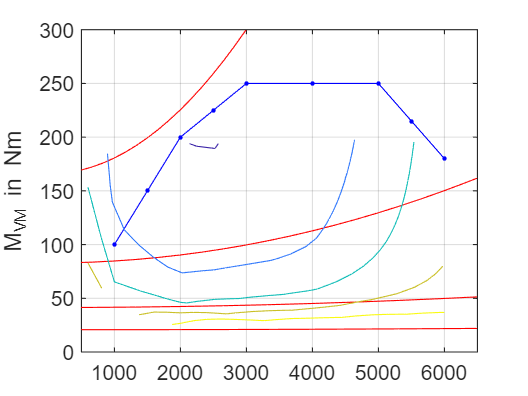

%mesh(nmo_range, mmo_range,  babs)
figure
 plot(n_VM_rpm,M_VM_Nm,'b.-')
    grid on
    hold on
    plot(n_W1_rpm,M_W1,'r')
    plot(n_W2_rpm,M_W2,'r')
    plot(n_W3_rpm,M_W3,'r')
    plot(n_W4_rpm,M_W4,'r')
    ylabel('M_{VM} in Nm')
    xlim([500 6500])
    ylim([0 300])
contour(nmo_temp, mmo_temp, b_e_temp, [250 275 300 325 350])






% https://de.mathworks.com/matlabcentral/fileexchange/69652-filled-area-plot?s_tid=srchtitle